% % clear all
% meandir = 'G:\DIC\stepsdMeanData.mat';
% load(meandir)
% steps(:,4) = sqrt(steps(:,1).^2 + steps(:,2).^2 + steps(:,3).^2);
% stp = 1:18;
% s = ['d','o','s','^'];
% ytx = ["U","V","W","Abs"];
% sys = [" 35mm"," 16mm"];
% titvar = [" Mean"," Standard deviation"];%];
% 
% for stat = 1:length(titvar)
%   for j = 1:2 %gets the system of the vendor (sys1 or sys2)
%     for pr = 1:4 %gets mean, std, min and max values for one step
%         vendord = [2 1 3];
%         for i= vendord %gets the vendor 
%             dispstr = sprintf('Current group is %g and system is %g for Vendor %g' ,i,j);
% %             disp(dispstr)
%          if j ~= 2 || i ~= 3
%             temp = meanPerFrame{i,j};
%          
%             for st = 1:18 %gets the step value
%                 curstep = temp{st}; 
%                 %Every column is data for one field 
%                 %first column is U, 2nd is V, 3rd is W and 4th is Abs.
%                 %displacement
%                 %First row is mean value, second row is standard deviation,
%                 %3rd is minimum value and 4th is the maximum value.
%                 
%                 if stat == 2
%                     vari(st) = curstep(pr,stat);
%                 else
%                     vari(st) = 1000*(curstep(pr,stat)-steps(st,pr));
%                 end
%                     
%             
%             end
%             if j == 1
%              fnl1(i,:,pr) = vari;
%             else
%              fnl2(i,:,pr) = vari;  
%             end
% 
%          end
%         end
%     end
%     
%    
%   end
% end


clc;clear all;close all;
dantec = [410 411 412 413 414;...
               420 421 422 423 424]; %group 3 system1 and 2 Dantec 
% matchID = [610];
lavision = [510,511,512 513 514;...
               520,521 522 523 524]; % LaVision
matchid = [610 611 612 613 614];

 vend = {dantec,lavision,matchid};

 %% Number of plots for legend

 grpdataset = 0;
for ven = 1:length(vend)
    sysgroups = vend{ven};
    for grp = 1:size(sysgroups,1)
        groups = sysgroups(grp,:);
        grpdataset = grpdataset + length(groups);
    end
    
end
        
%%
% linclr = jet(grpdataset);%parula(length(vend));
% linclr = [0 0.4470 0.7410;0.8500 0.3250 0.0980;0.9290 0.6940 0.1250];
linPro = "-.";%,"-.","-."];


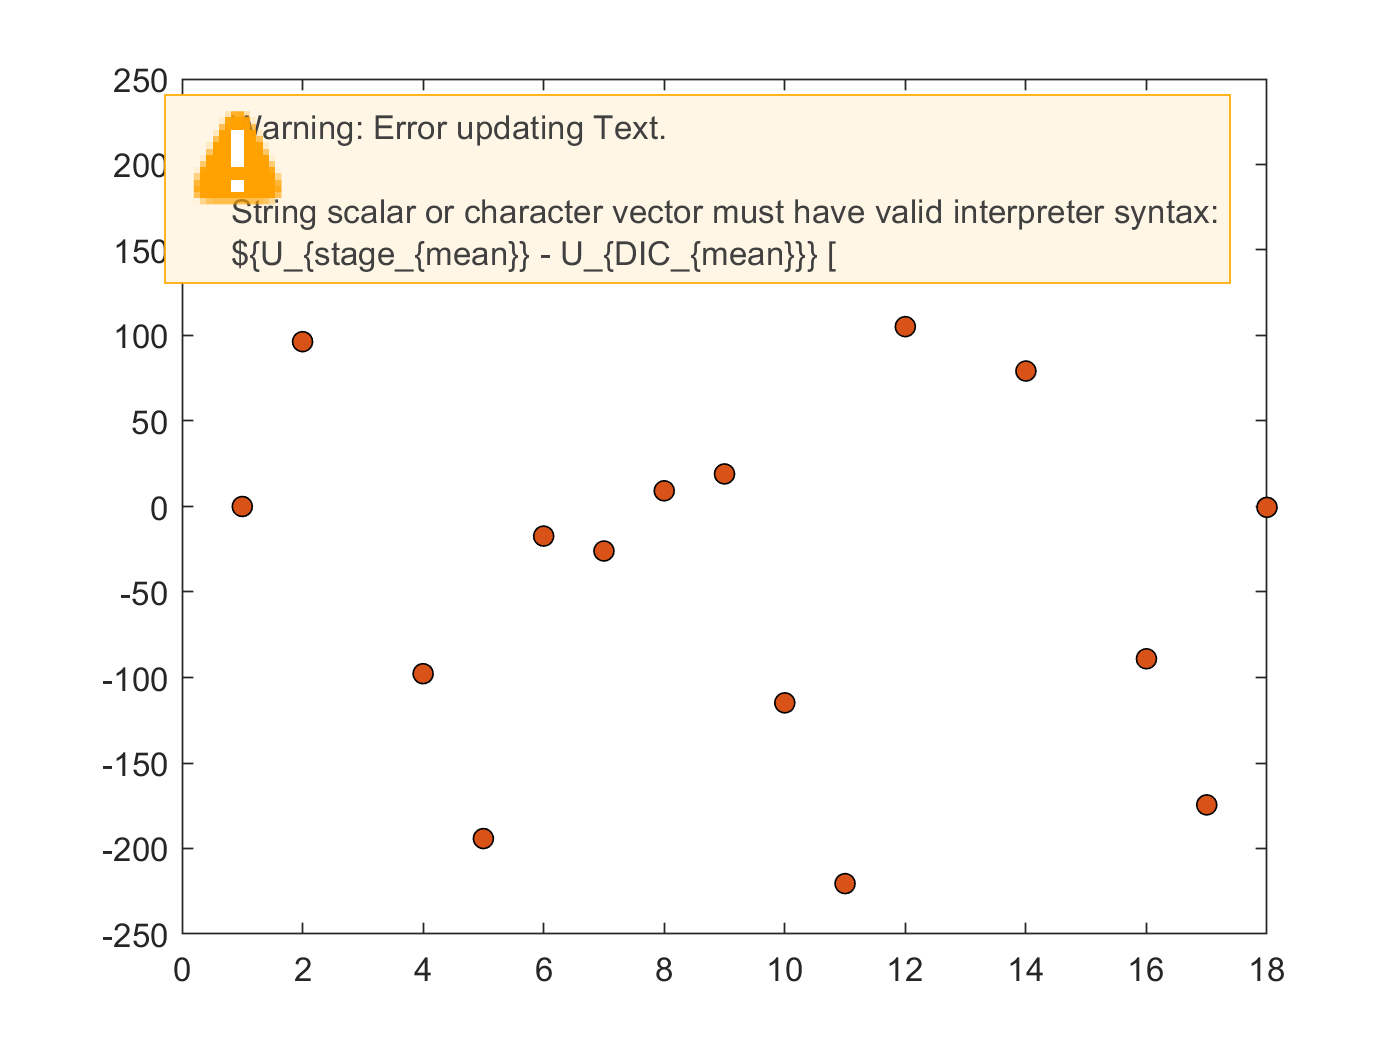

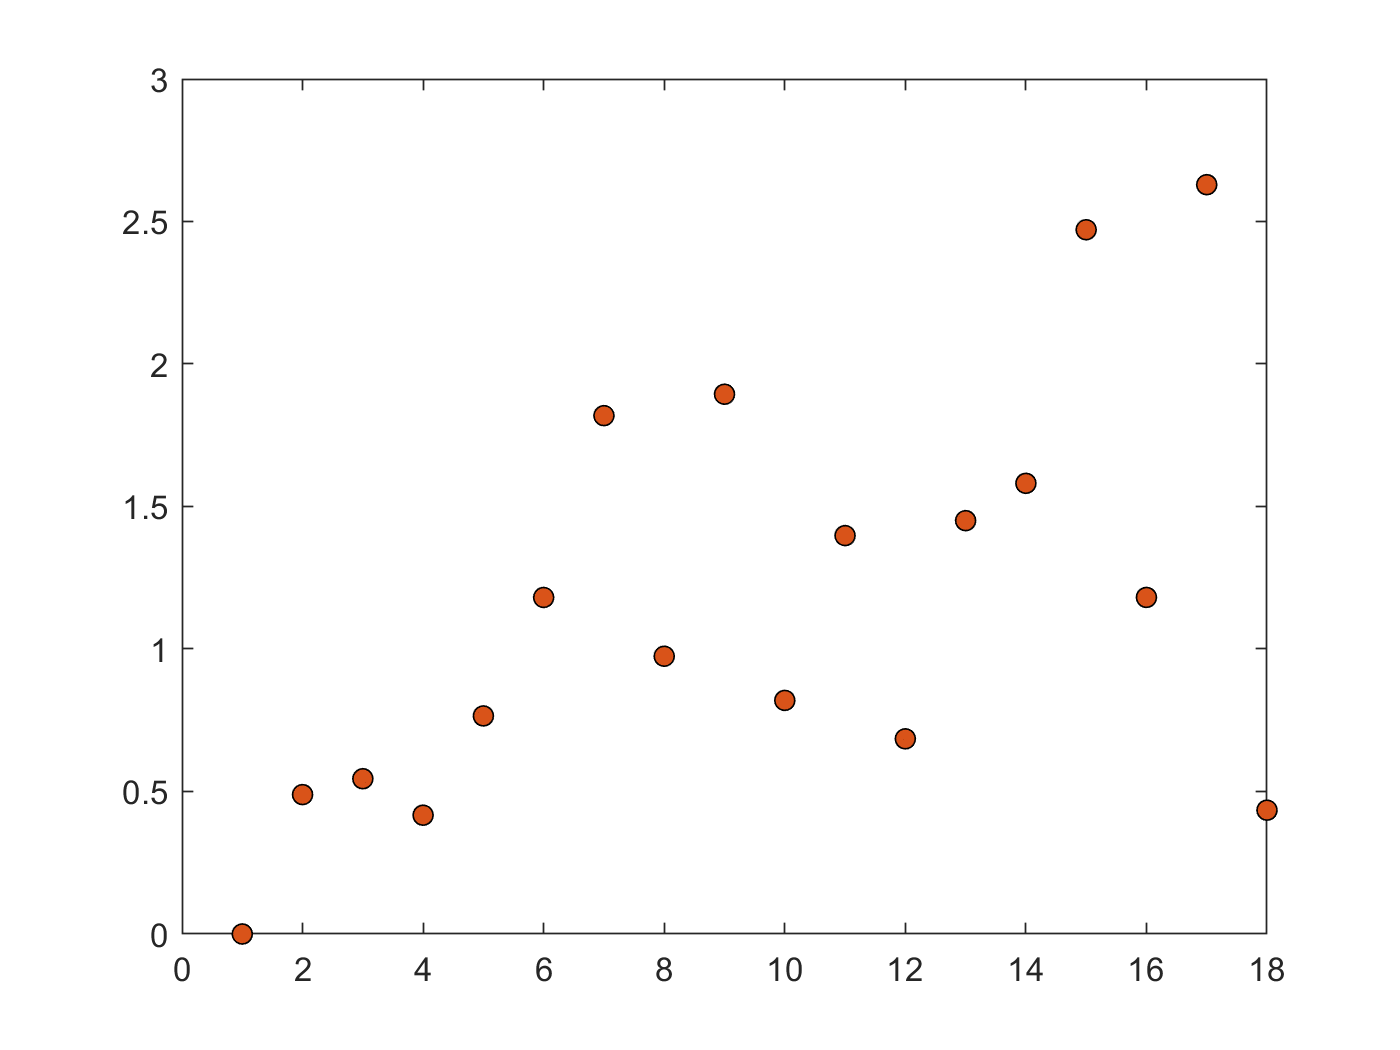

linclr = [0.8500 0.3250 0.0980;0 0.4470 0.7410;0.9290 0.6940 0.1250;0.4940 0.1840 0.5560;0.6350 0.0780 0.1840;0.4660 0.6740 0.1880];
marker = ["o","s","d"];
dispVar = ["U","V","W","Abs."];
meandir = 'D:\DIC\stepsdMeanData.mat';
venNum = [4,5,6];
load(meandir)
steps(:,4) = sqrt(steps(:,1).^2 + steps(:,2).^2 + steps(:,3).^2);
steps = steps';
rng(5)
for disp = 1:4
    
    for vn = 1:length(vend)
        sysgroups = vend{vn};
%     groupID = grpid(vn);
        clrCounter = 0;
        curMark = marker(vn);
        for grp = 1:size(sysgroups,1)
            if ~(vn==3 && grp==2)
             mpfvg = squeeze(meanPerFrame(vn,grp,:)); %number of datasets
            
             clrind = randi(length(linclr),1,5);
              for igroupNum= 1
                  
                  temp = mpfvg{igroupNum}; %frames
                  meanData = squeeze(temp(:,1,:));
                  stdData = squeeze(temp(:,2,:));
                  minData = squeeze(temp(:,3,:));
                  maxData = squeeze(temp(:,4,:));
                  meanDif = steps-meanData;
                     figure(1)
                     clrCounter = clrCounter + 1;
%                      plot(1:18,1000*meanDif(disp,:),curMark,'Color',linclr(clrind(igroupNum),:),'MarkerFaceColor',linclr(clrind(igroupNum),:),'MarkerEdgeColor','k')
                     plot(1:18,1000*meanDif(disp,:),curMark,'Color',linclr(clrCounter,:),'MarkerFaceColor',linclr(clrCounter,:),'MarkerEdgeColor','k')
                     
                     hold on

                     figure(2)
                     plot(1:18,1000*stdData(disp,:),curMark,'Color',linclr(clrCounter,:),'MarkerFaceColor',linclr(clrCounter,:),'MarkerEdgeColor','k') 
                     hold on

                 
              end  

            end
        end
    end
    figure(1)
    f = gca;
% f.View = [30,30];
       f.TickDir = 'in';
%        f.XMinorTick = 'on';
       f.YMinorTick = 'on';
       f.XGrid = "on";
       f.YGrid = "on";
% f.ZMinorTick = 'on';
       f.Box = 'on';
       f.BoxStyle = 'back';
%        f.XMinorGrid = 'on';
       f.YMinorGrid = 'on';
       titStr = sprintf("${%s_{stage_{mean}} - %s_{DIC_{mean}}} [\\mu m]$",dispVar(disp),dispVar(disp));
%        tit = title(titStr,'Interpreter','latex'); tit.FontSize = 13;
       xlabel('Frame Number','Interpreter','latex','FontSize',13)
       ylabStr = sprintf("${%s_{stage_{mean}} - %s_{DIC_{mean}}} [\\mu m]$",dispVar(disp),dispVar(disp));
       ylabel(ylabStr,'Interpreter','latex','FontSize',13)
        
       lgd = legend('4','5','6');
       htitle = get(lgd,'Title');
       set(htitle,'String','Participant:')
%        lgd.Title = 
       lgd.Location = 'best';
       lgd.Interpreter = 'latex';
        
       figure(2)
    f = gca;
% f.View = [30,30];
       f.TickDir = 'in';
%        f.XMinorTick = 'on';
       f.YMinorTick = 'on';
       f.XGrid = "on";
       f.YGrid = "on";
% f.ZMinorTick = 'on';
       f.Box = 'on';
       f.BoxStyle = 'back';
%        f.XMinorGrid = 'on';
       f.YMinorGrid = 'on';
       titStr = sprintf("${%s_{stage_{mean}} - %s_{DIC_{mean}}} [\\mu m]$",dispVar(disp),dispVar(disp));
%        tit = title(titStr,'Interpreter','latex'); tit.FontSize = 13;
       xlabel('Frame Number','Interpreter','latex','FontSize',13)
       ylabStr = sprintf("${%s_{stage_{mean}} - %s_{DIC_{mean}}} [\\mu m]$",dispVar(disp),dispVar(disp));
       ylabel('Standard Deviation [$\mu m$]','Interpreter','latex','FontSize',13)

       lgd = legend('4','5','6');
       htitle = get(lgd,'Title');
       set(htitle,'String','Participant:')
       lgd.Location = 'best';
       lgd.Interpreter = 'latex';
end


% for iven = 1:size(meanPerFrame,1)
%     igrp =







steps(:,4) = sqrt(steps(:,1).^2 + steps(:,2).^2 + steps(:,3).^2);
stp = 1:18;
s = ['d','o','s','^'];
clrs = [0.8500 0.3250 0.0980;0 0.4470 0.7410;0.9290 0.6940 0.1250];
ytx = ["U","V","W","Abs"];
ytx1 = ["U","V","W","D"];
sys = [" 35mm"," 16mm"];
titvar = [" Mean"," Standard deviation"];%," Minimum"," Maximum"];
uld = [-300 300]; uls = [0 1000*0.035];
uldsd = [-100 100]; ulssd = [0 1000*0.035];

for stat = 1:length(titvar)
  for j = 1:2 %gets the system of the vendor (sys1 or sys2)
    for pr = 1:4 %gets mean, std, min and max values for one step
        vendord = [2 1 3];
        fig = set(gcf,'Renderer','opengl','color','white','Units','Normalized',...
       'Outerposition',[0.553,0.3648,0.3461,0.4060]);

        for i= vendord %gets the vendor 
            dispstr = sprintf('Current group is %g and system is %g for Vendor %g' ,i,j);
%             disp(dispstr)
       if j ~= 2 || i ~= 3
        temp = meanPerFrame{i,j};
         
            for st = 1:18 %gets the step value
                curstep = temp{st}; 
                %Every column is data for one field 
                %first column is U, 2nd is V, 3rd is W and 4th is Abs.
                %displacement
                %First row is mean value, second row is standard deviation,
                %3rd is minimum value and 4th is the maximum value.
                
                if stat == 2
                    vari(st) = 1000*curstep(pr,stat);
                else
                    vari(st) = 1000*(curstep(pr,stat)-steps(st,pr));
                end
                    
            
            end
            plot(stp,vari,s(pr),'MarkerEdgeColor',clrs(i,:),'MarkerFaceColor',clrs(i,:))
            xlim([0 19])
            if stat == 1  
                if pr ~= 4
                    ylim(uld)
                else
                    ylim(uldsd)
                end
            else
                ylim(uls)
            end
            hold on
        end
        end
        %sprintf
        if stat == 1
            mainvar = sprintf('%s$_{mean}$ - %s$_{stage}$',ytx1(pr),ytx1(pr));
        else
            mainvar = sprintf('Standard deviation of %s$_{mean}$ - %s$_{stage}$',ytx1(pr),ytx1(pr));%' D$_{mean}$-D$_{stage}$';
        end
        titst = strcat(mainvar,' for',sys(j),' system');
        title(titst,'Interpreter',"latex",'FontSize',14)
        lgdTitSys = strcat('Group',' (Sys : ',sys(j),')');
       lgd = legend('1','2','3'); %lgd.Title.String= lgdTitSys; 
       lgd.Interpreter = 'latex'; lgd.Location = 'best';
       lgd.NumColumns = 1;
       xlabel('Translation step','Interpreter',"latex",'FontSize',12)
       if stat == 2
           ytxt = strcat(ytx(pr),' Disp.',' (error)',' [$\mu$m]');
       else
           ytxt = strcat(ytx(pr),' Disp.',' (error)',' [$\mu$m]');
       end
       
       ylabel(ytxt,'Interpreter',"latex",'FontSize',12)
       f = gca;
% f.View = [30,30];
       f.TickDir = 'in';
%        f.XMinorTick = 'on';
       f.YMinorTick = 'on';
       f.XGrid = "on";
       f.YGrid = "on";
% f.ZMinorTick = 'on';
       f.Box = 'on';
       f.BoxStyle = 'back';
%        f.XMinorGrid = 'on';
       f.YMinorGrid = 'on';
        hold off
        drawnow
        framename = sprintf('sys%g%s d%s.pdf',j,titvar(stat),ytx(pr));
        framename = framename(~isspace(framename));
        fieldP = fullfile('D:\DIC\Statistics',framename);
%         exportgraphics(gcf,fieldP,'Resolution',600)
        
        clf;
        %exportgraphics will come here
% f.ZMinorGrid = 'on';
    end
    
   
  end
end
